# Sample 13-1

## 辞書学習

カルーネン-レーベ変換（主成分分析）

画像処理特論

村松 正吾 

動作確認: MATLAB R2020a

## Dictionary learning

Karhunen–Loève transform (principle component analysis) 

Advanced Topics in Image Processing

Shogo MURAMATSU

Verified: MATLAB R2020a

### 準備

(Preparation)

clear 
close all
import msip.download_img
msip.download_img

lena.png already exists in ./data/
baboon.png already exists in ./data/
goldhill.png already exists in ./data/
barbara.png already exists in ./data/


### パラメータ設定

(Parameter settings)

- ブロックサイズ (Block size)

szBlock = [ 8 8 ];

## 画像の読込

(Read image)

- 
$$\mathbf{u}\in\mathbb{R}^{N}$$


u = rgb2gray(im2double(imread('./data/lena.png')));
meanu = mean(u(:));

## カルーネン-レーベ変換（主成分分析）

(Karhunen–Loève transform (principle component analysis))

#### 問題設定 (Problem setting):

        
$$\widehat{\mathbf{\Phi}}=\arg \max _{\mathbf{\Phi}\in\mathbb{R}^{M\times M}} \mathrm{tr}\left(\mathbf{\Phi}_{:, 1: p}^{T} \widehat{\mathbf{\Sigma}}_{y} \mathbf{\Phi}_{:, 1: p}\right), \text { s.t. } \mathbf{\Phi}^{T} \mathbf{\Phi}=\mathbf{I}_{M}, \forall p \in\{1,2, \cdots, M\}$$


ただし， $\widehat{\mathbf{\Sigma}}_{y}$は 観測ベクトル $\{\mathbf{y}_n\}_n$ （零平均を仮定）の標本分散共分散行列 (where， $\widehat{\mathbf{\Sigma}}_{y}$ is the sample covariance matrix of the observation vectors $\{\mathbf{y}_n\}_n$ (assumed to have zero mean:)

        
$$\widehat{\mathbf{\Sigma}}_{y}=\frac{1}{S-1}\sum_{n=1}^{S}\mathbf{y}_n\mathbf{y}_n^T$$


#### 解 (Solution):

固有値分解 (Eigendecomposition) 

        
$$\widehat{\mathbf{\Phi}}^T\widehat{\mathbf{\Sigma}_y}\widehat{\mathbf{\Phi}}=\mathbf{\Lambda}
$$


ただし， $\mathbf{\Lambda}=\mathrm{diag}(\lambda_1,\lambda_2,\cdots,\lambda_M)$． $\lambda_1\geq\lambda_2\geq\cdots\lambda_M$ は $\widehat{\mathbf{\Sigma}}_{y}$の固有値．(where,  $\mathbf{\Lambda}=\mathrm{diag}(\lambda_1,\lambda_2,\cdots,\lambda_M)$． $\lambda_1\geq\lambda_2\geq\cdots\lambda_M$ are the eigenvalues of $\widehat{\mathbf{\Sigma}}_{y}$.)

画像 $\mathbf{u}$からのデータ行列 $\mathbf{Y}$ の生成 (Generation of data matrix  $\mathbf{Y}$  of image $\mathbf{u}$)

Y = im2col(u,szBlock,'distinct');
Y = Y - mean(Y,2);

標本分散共分散行列 $\widehat{\mathbf{\Sigma}}_{y}$の計算 (Calculation of sample covariance matrix $\widehat{\mathbf{\Sigma}}_{y}$)

SigmaY = cov(Y.');

標本分散共分散行列 $\widehat{\mathbf{\Sigma}}_{y}$の固有値分解 (Eigendecomposition of sample covariance matrix  $\widehat{\mathbf{\Sigma}}_{y}$)

[Phi,Lambda] = eig(SigmaY);

固有値 $\lambda$ の大きさの降順に列ベクトルをソート (Sorting column vectors in the descending order of the eigenvalues $\lambda$)

[~,idx] = sort(diag(Lambda),'descend');
Phi = Phi(:,idx);

固有ベクトルを基底画像に変換 (Reshape the eigenvectures into basis images)

D = col2im(Phi,szBlock,szBlock.^2,'distinct');

### 画像表示

(Image show)

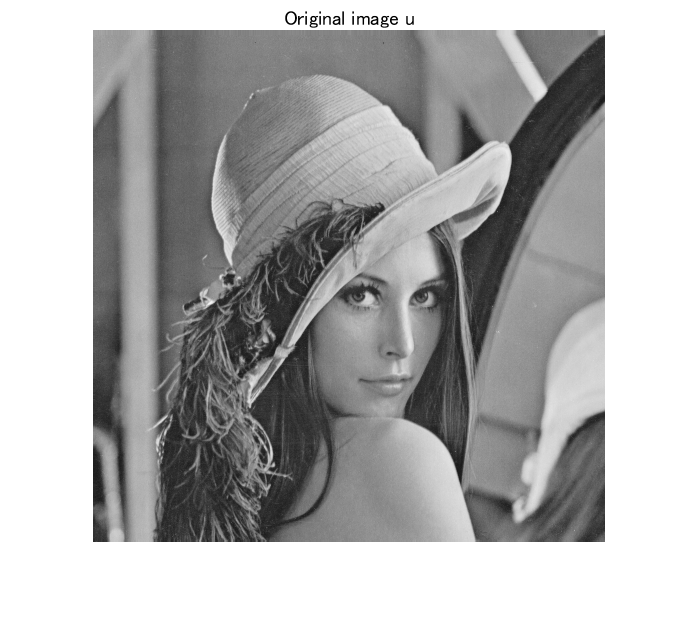

figure(1)
imshow(u);
title('Original image u')

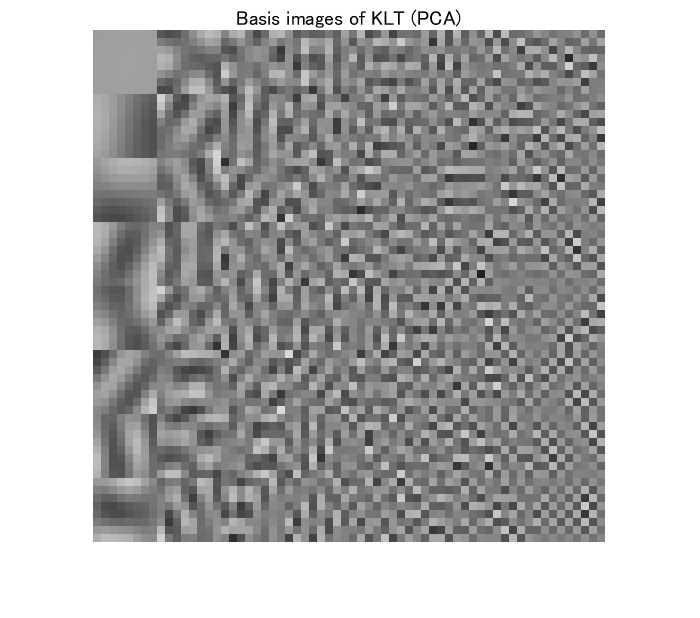

figure(2)
imshow(imresize(D+.5,8,'nearest'))
title('Basis images of KLT (PCA)')

© Copyright, Shogo MURAMATSU, All rights reserved.